**The Tabular value-fucntion methods on the cart and pole system**

Consider the cart-and-pole system here depicted:

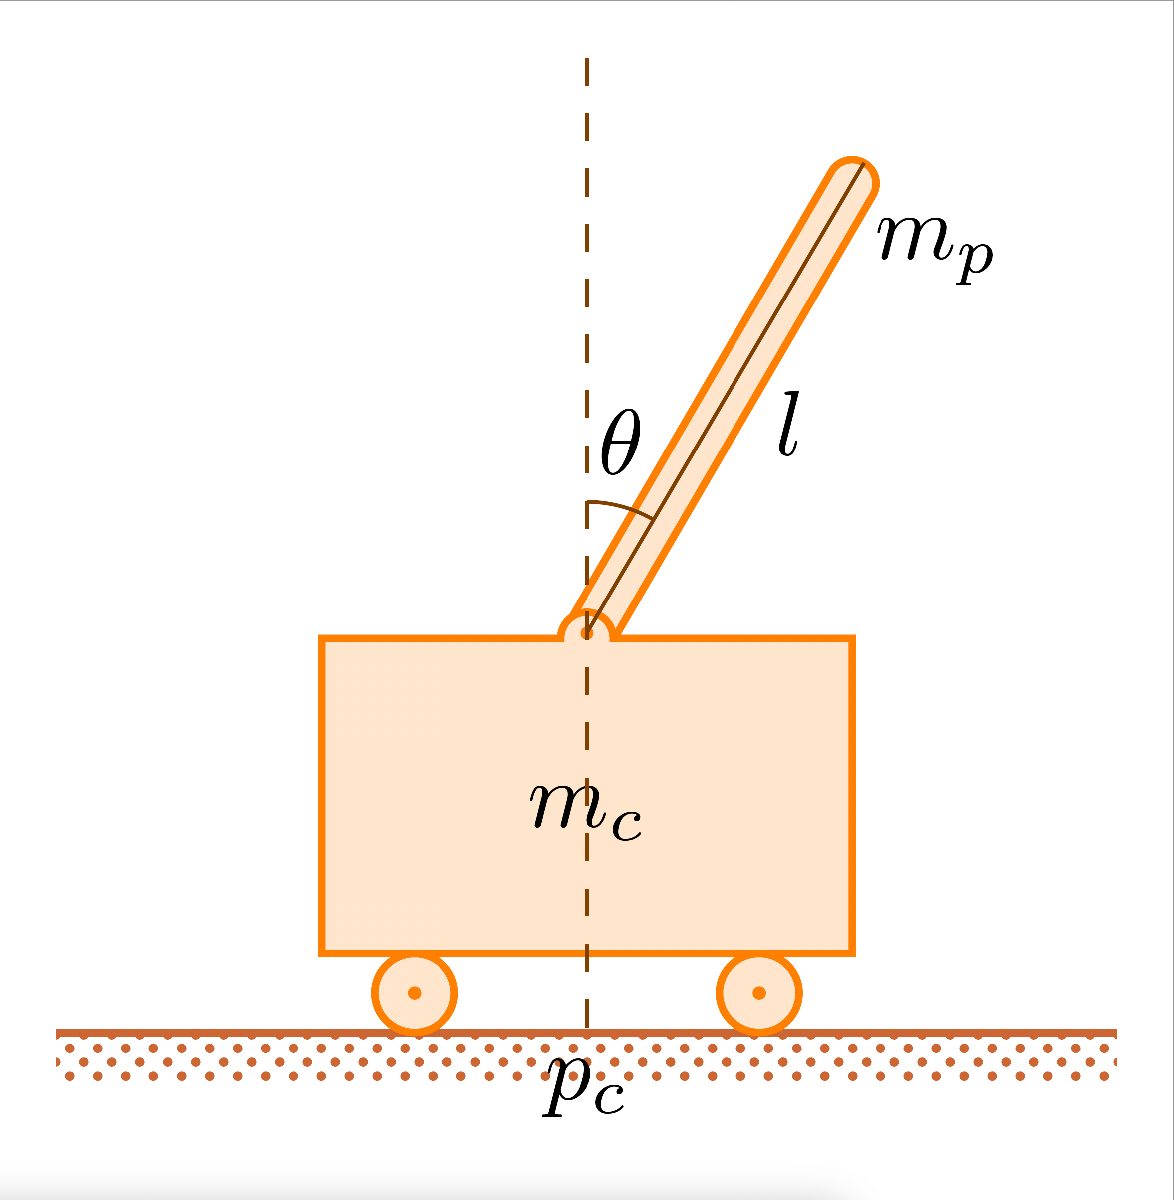

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient.

- Given the $$\mathcal{X}$$set, select centers and standard deviation of RBFs and create a code that given a state $x$returns $\phi\left(x,\cdot\right)$

The $$\mathcal{X}$$ set will be compact and it a subset of $$\mathcal{R}$$, $$\mathcal{X}$$$$\subset$$$$\mathcal{R}$$

% Define the RBF centers and standard deviations
clc;
clear all;



Look to  phi_x=RBF(x_initial,u,combinations) at the end of the code.

% Function to evaluate the RBF network

        2. Create a code that applies Q-Learning algorithm with function approximation

tic

% RBF parameters

rbf_centers1=[deg2rad(-12) deg2rad(-6) deg2rad(-3) 0 deg2rad(3) deg2rad(6) deg2rad(12)];
rbf_centers2=[-0.75 -0.5 -0.25 0 0.25 0.5 0.75];
rbf_centers3=[-0.75 -0.5 -0.25 0 0.25 0.5 0.75];
rbf_centers4=[-0.75 -0.5 -0.25 0 0.25 0.5 0.75];


% Use ndgrid to create grid matrices
[X1, X2, X3, X4] = ndgrid(rbf_centers1,rbf_centers2,rbf_centers3,rbf_centers4);

% Reshape the matrices into column vectors
num_combinations = numel(X1);
combinations = [reshape(X1, num_combinations, 1), reshape(X2, num_combinations, 1), ...
                reshape(X3, num_combinations, 1), reshape(X4, num_combinations, 1)];


num_actions=2;% 10 -10
% Initialize Q-function parameters
theta = rand(size(combinations,1) * num_actions, 1);





% Repeating for each episode
% Provide the code
tic

% Q-learning parameters
alpha = 0.002;  % Learning rate
gamma = 0.94;  % Discount factor
%Tradeoff  between exploration and eploitation
tot_episode =1200; %total number of episode to perform
N=200; %totale number of steps for each episode
U=0;%initializing the input 
timestep=0.02;

reward_sum=0;% Initializing the total reward for each episode 
episodes_reward=zeros(tot_episode,1);%store reward sum for each episode
% Repeating for each episode 
last_episode=zeros(4,1);
which_episode=0

which_episode = 0

for j=1:tot_episode
   
     x_initial=[rand(1,1)*0.01,0,rand(1,1)*0.01,0];%random initial condition


     reward_sum=0;%
   

        for i = 1:N

           if (x_initial(1)<=deg2rad(-12)) || (x_initial(1)>=deg2rad(12)) || (x_initial(3)<=-1) || (x_initial(3)>=1)
              % x_initial(3);

               %disp('positio'+ x_initial(3))
           break;
           end
     if i>=150
 
    which_episode=[which_episode,j] ;

     end
         
        u=epsilonGreedyPolicy(x_initial,j,combinations,theta,tot_episode);
        if j==tot_episode 

        last_episode=[last_episode,x_initial'];
        end
          stateNext=UpdateDynamics(x_initial,u)';

    
        reward = computeReward(stateNext);  %  reward function
   
        reward_sum=reward_sum+(gamma^(i-1))*reward;
        episodes_reward(j)=reward_sum;
  
      
        Q=allQ(theta,x_initial,u, combinations,stateNext);%Q(1) for x(k),u(k)   Q(2) for x(k+1) 10  Q(3) for x(k+1) -10
 
        theta=theta+alpha*(reward+gamma*max(Q(2),Q(3))-Q(1))*RBF(x_initial,u,combinations);

        x_initial=stateNext;

        end
end
toc

Elapsed time is 1862.774248 seconds.


% Example functions to be replaced with your actual implementations

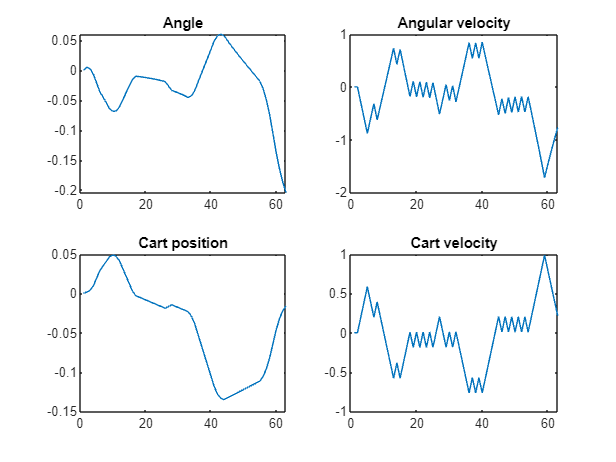


figure()
title("Q learning")
subplot(2,2,1)
plot(1:size(last_episode,2),last_episode(1,:))

title('Angle');
subplot(2,2,2)
plot(1:size(last_episode,2),last_episode(2,:))

title('Angular velocity');
subplot(2,2,3)
plot(1:size(last_episode,2),last_episode(3,:))

title('Cart position');
subplot(2,2,4)

plot(1:size(last_episode,2),last_episode(4,:))
title('Cart velocity');

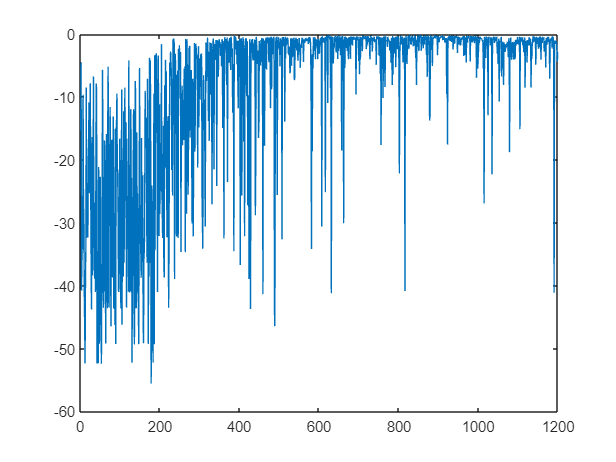

figure()
plot(episodes_reward)

        3. Copy and paste your Q-learning algorithm with function approximation and apply the changes needed to convert it into a SARSA algorithm with function approximation 

% Provide the code
% RBF parameters

rbf_centers1=[deg2rad(-12) deg2rad(-6) deg2rad(-3) 0 deg2rad(3) deg2rad(6) deg2rad(12)];
rbf_centers2=[-0.75 -0.5 -0.25 0 0.25 0.5 0.75];
rbf_centers3=[-0.75 -0.5 -0.25 0 0.25 0.5 0.75];
rbf_centers4=[-0.75 -0.5 -0.25 0 0.25 0.5 0.75];


% Use ndgrid to create grid matrices
[X1, X2, X3, X4] = ndgrid(rbf_centers1,rbf_centers2,rbf_centers3,rbf_centers4);

% Reshape the matrices into column vectors
num_combinations = numel(X1);
combinations = [reshape(X1, num_combinations, 1), reshape(X2, num_combinations, 1), ...
                reshape(X3, num_combinations, 1), reshape(X4, num_combinations, 1)];


num_actions=2;% 10 -10
% Initialize Q-function parameters
theta = zeros(size(combinations,1) * num_actions, 1);



alpha = 0.001;  % Learning rate
gamma = 0.95;  % Discount factor
%Tradeoff  between exploration and eploitation
tot_episode =1000; %total number of episode to perform
N=200; %totale number of steps for each episode
U=0;%initializing the input 

reward_sum=0;% Initializing the total reward for each episode 
episodes_reward1=zeros(tot_episode,1);%store reward sum for each episode
% Repeating for each episode 
last_episode1=zeros(4,1);





for j=1:tot_episode
   
     x_initial=[rand(1,1)*0.01,0,rand(1,1)*0.01,0];%random initial condition

     u=epsilonGreedyPolicySARSA(x_initial,j,combinations,theta);%perform epsilon greedy policy

     reward_sum=0;%initializing total reward for each episode
   

  

        for i = 1:N

           if (x_initial(1)<=deg2rad(-12)) || (x_initial(1)>=deg2rad(12)) || ((x_initial(3)<=-1) || (x_initial(3)>=1 )) %terminal condition on angle and position
           break;
           end
     
        stateNext=UpdateDynamics(x_initial,u)'; %x(k+1)
        
        reward = computeReward(stateNext); %computing r(k+1)
      
        if u==-10 
            actionIndex=1;
        else
            actionIndex=2;
        end

        if j==tot_episode 
     
        last_episode1=[last_episode1,x_initial'];%saving last episode

        end

        u_next=epsilonGreedyPolicySARSA(stateNext,j,combinations,theta); %u(k+1)

        reward = computeReward(stateNext);  %  reward function
   
        reward_sum=reward_sum+(gamma^(i-1))*reward;
        episodes_reward1(j)=reward_sum;
  
  
      
        Q=allQSARSA(theta,x_initial,u, combinations,stateNext,u_next);%Q(1) for x(k),u(k)   Q(2) for x(k+1) 10  Q(3) for x(k+1) -10
 alpha = alpha * 0.995;
        theta=theta+alpha*(reward+gamma*Q(2)-Q(1))*RBF(x_initial,u,combinations);
    %evaluating if the states are out of bounds and then finish the episode in
       x_initial=stateNext;
    u=u_next;
       
        end
end



toc

Elapsed time is 17244.439286 seconds.


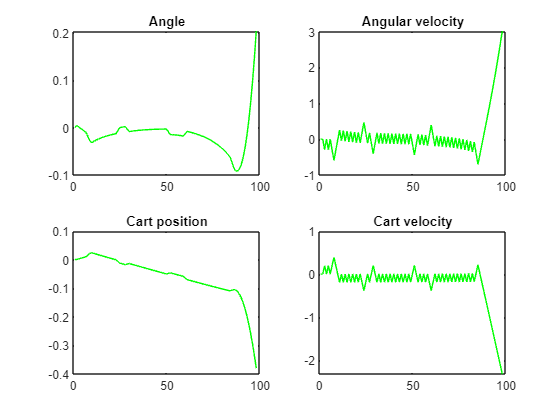

RBF(x_initial,u,combinations);
figure()
subplot(2,2,1)
plot(1:size(last_episode1,2),last_episode1(1,:),'g')

title('Angle');
subplot(2,2,2)
plot(1:size(last_episode1,2),last_episode1(2,:),'g')

title('Angular velocity');
subplot(2,2,3)
plot(1:size(last_episode1,2),last_episode1(3,:),'g')

title('Cart position');
subplot(2,2,4)

plot(1:size(last_episode1,2),last_episode1(4,:),'g')
title('Cart velocity');

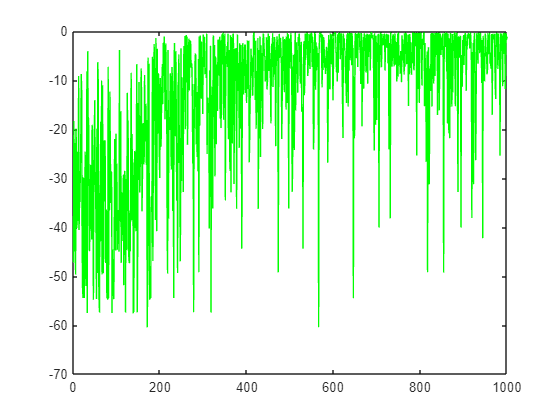




figure()
plot(episodes_reward1,'g')


figure();

plot(episodes_reward1,'b','DisplayName','Q learning');

Unrecognized function or variable 'episodes_reward'.

hold on ;
plot (episodes_reward1,'g','DisplayName','SARSA');
title('Q Learning vs SARSA');
% Adding legend with specified colors
legend('Q learning', 'SARSA', 'TextColor', 'blue', 'Color', 'w', 'Location', 'southeast')

Comparison between tabular Q learning and function approximation: Hands on 4 VS Hands on 5

Tabular Q learning is simpler and easier to implement for a limited number of states action pair, in addition provides a clear representation of the learned values for each state-action pair, that can be seen in the Q table.

On the other hand Tabular Q-learning becomes impractical when dealing with large state or action space. Here Q learning with Functional approximation come to help.

Continuous state and action spaces can be handled more effectiively but  implementing Q-learning with function approximation is more complex involving more effort to achieve a proper stability and convergence. In addition regarding Interpretability, Q learning with Functional approximation is harder to interpret and understand the learned policy.

Overall ,the results of tabular Q learning are better than with function approximation, probably with putting more effort in searching the right parameters for the learning rate,discount factor or modifying properly the reward or the epsilon greedy policy,,better results could be achieved having a good trade-off between exploitaition and exploration. In addition shorter episodes has been studied (200 steps of duration 0.02) in this hands on due to low computing power available.

However in both cases for SARSA and Q learning a positive trend of the rewards of each episode is achieved.

As you can see here, the function approximation method is less effective to perform the task  comparing to the Q tabular method.

function reward=computeReward(state)

     
     reward=-norm([state(1),state(3)]);

    if (state(1)<=deg2rad(-12)) || (state(1)>=deg2rad(12)) || ((state(3)<=-1) || (state(3)>=1))
        reward=reward-90;
    end


end





function phi_x=RBF(x_initial,u,combinations)
phi=0;
var=0.1;

for i=1:1:size(combinations,1)
phi=[phi,exp((-norm(x_initial-combinations(i,:))^2)/(2*var^2))];
%phi=[phi, cos(pi*combinations(i,:)*x_initial')];
end
phi=phi(2:end);
if u==-10
    phi_x=[phi,zeros(1,size(combinations,1))]';
else
    phi_x=[zeros(1,size(combinations,1),1), phi]';

end

end

function Qall=allQ(theta,x_initial,u, combinations,stateNext)
 
Q=theta'*RBF(x_initial,u,combinations);
Q10=theta'*RBF(stateNext,10,combinations);
Qmin10=theta'*RBF(stateNext,-10,combinations);
Qall=[Q Q10 Qmin10];

end


function Qall=allQSARSA(theta,x_initial,u, combinations,stateNext,u_next)
 
Q=theta'*RBF(x_initial,u,combinations);
Qnext=theta'*RBF(stateNext,u_next,combinations);

Qall=[Q Qnext];

end





function u = epsilonGreedyPolicy(state, j, combinations,theta,tot_episode )
    
 
    initial_exploration_episode = 160; 
    
    
   if j <= initial_exploration_episode
        % Initial exploration phase
        epsilon = inf;%to permit exploration at the beginning
   else
        epsilon = initial_exploration_episode/ j ;

      %  epsilon = max(0.01, epsilon * 0.995)
    end
    if rand() <= epsilon
        % Explore: Choose a random action
        selectedAction = randi(2);
        u = (selectedAction * 2 - 3) * 10; % Map index to action value
    else
        % Exploit: Choose the action with the highest estimated value
  

     
Q10=theta'*RBF(state,10,combinations);
Qmin10=theta'*RBF(state,-10,combinations);
        % Check if multiple actions have the same highest value
     if Qmin10==max(Q10,Qmin10)
            u=-10;
     else
         u=10;
        
     end
      
    end
end

function u = epsilonGreedyPolicySARSA(state, j, combinations,theta )
    
    initial_exploration_episode = 130; 
    
    
  if j <= initial_exploration_episode
        % Initial exploration phase
        epsilon = inf;%to permit exploration at the beginning
   else
        epsilon = initial_exploration_episode/ j ;
       epsilon = max(0.2, epsilon * 0.995);
    end
 

       
      %  epsilon = max(0.01, epsilon * 0.995)
   
    if rand() <= epsilon
        % Explore: Choose a random action
        selectedAction = randi(2);
        u = (selectedAction * 2 - 3) * 10; % Map index to action value
    else
        % Exploit: Choose the action with the highest estimated value

Q10=theta'*RBF(state,10,combinations);
Qmin10=theta'*RBF(state,-10,combinations);
        % Check if multiple actions have the same highest value
     if Qmin10==max(Q10,Qmin10)
            u=-10;
     else
         u=10;
        
     end
      
    end
end


function X_nl = UpdateDynamics(conds, u)
  % constants definition
g = 9.8; % gravitational acceleration
mc = 1;   % cart mass [kg]
l = 0.5; % half-pole length [m]
mp = 0.1; % pole mass [kg]
mup = 0.000002; % pole friction coefficient
t2=0;
X_nl = conds';
timestep = 0.02;
to_finish=0;
cont=true;
    t2=0;
    t1 = t2;
    t2 = t2+timestep;
    time = [t1, t2];
    [t,state] = ode45(@(t,x)solving1(t, x, g, u, mp, l, mc, mup), time, conds);
    tp = find(t == t2);
    conds = state(tp,:);
    X_nl = conds';
end



